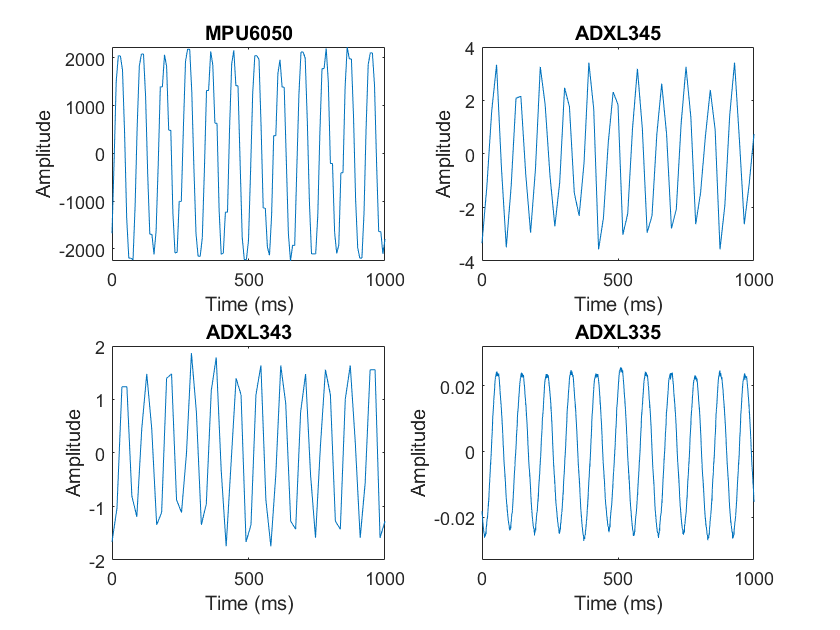

timeLimits = [0 0.1]; % seconds
t = linspace(0,1000, 131);
MPU6050_ROI = MPU6050(:);
sampleRate = 1300; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(MPU6050_ROI)-1))+1;
MPU6050_ROI = MPU6050_ROI(minIdx:maxIdx);
subplot(2,2,1)
plot(t,MPU6050_ROI)
title('MPU6050')
ylabel('Amplitude')
xlabel('Time (ms)')


ADXL345_ROI = ADXL345(:);
t = linspace(0,1000, 57);
sampleRate = 560; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(ADXL345_ROI)-1))+1;
ADXL345_ROI = ADXL345_ROI(minIdx:maxIdx);
subplot(2,2,2)
plot(t,ADXL345_ROI)
title('ADXL345')
ylabel('Amplitude')
xlabel('Time (ms)')

ADXL343_ROI = ADXL343(:);
t = linspace(0,1000, 56);
sampleRate = 550; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(ADXL343_ROI)-1))+1;
ADXL343_ROI = ADXL343_ROI(minIdx:maxIdx);
subplot(2,2,3)
plot(t,ADXL343_ROI)
title('ADXL343')
ylabel('Amplitude')
xlabel('Time (ms)')

ADXL335_ROI = ADXL335(:);
t = linspace(0,1000, 10001);
sampleRate = 100000; % Hz
startTime = 0; % seconds
minIdx = ceil(max((timeLimits(1)-startTime)*sampleRate,0))+1;
maxIdx = floor(min((timeLimits(2)-startTime)*sampleRate,length(ADXL335_ROI)-1))+1;
ADXL335_ROI = ADXL335_ROI(minIdx:maxIdx);
subplot(2,2,4)
plot(t,ADXL335_ROI)
title('ADXL335')
ylabel('Amplitude')
xlabel('Time (ms)')

subplot(2,2,4)
ylim([-0.033 0.032])